clearvars;
%U0 = rand(16,1);
a = ones(8,1);
U0 =[a;randn(8,1)];


T = 0.1;
N = 2^15;
dT = T/(N-1);
tslow = 4000/(2.2*1e+6);
h = 2*pi*dT/tslow;
Uevalution = zeros(16,N);
Uevalution(:,1) = U0;
U1 = U0;

for i = 2:N
  U1 = U1 + h*f(U1);  
  Uevalution(:,i) = U1;

end


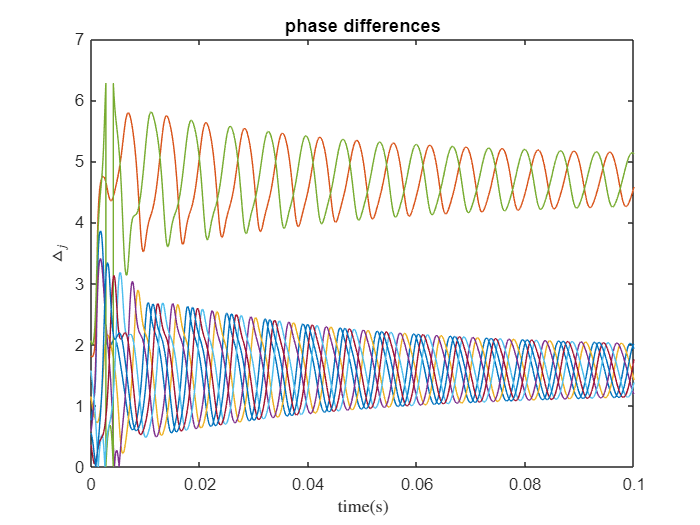


phi = Uevalution(9:end,:);
AD1 = circshift(eye(8),1,2);
dj = abs(rem((AD1*phi - phi),2*pi));
aj = Uevalution(1:8,:);

%plot(abs(rem(phi,2*pi)))
plot(0:dT:T,dj)
title("phase differences")
ylabel('$\triangle_j$','Interpreter','latex')
xlabel("time(s)",'Interpreter','latex')

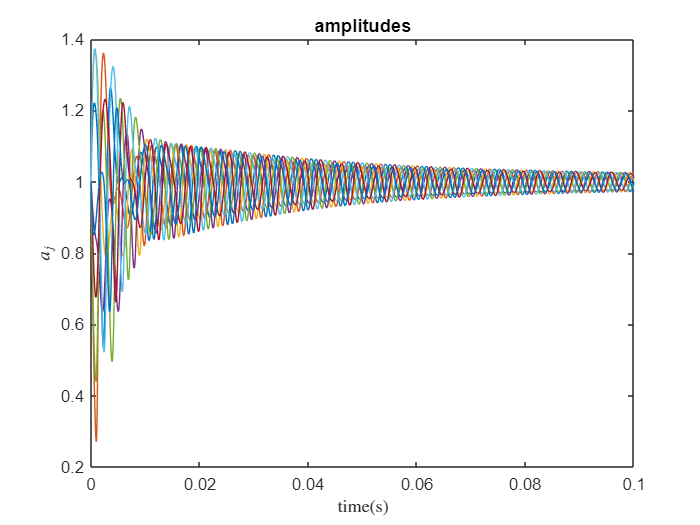

plot(0:dT:T,aj)
title("amplitudes")
ylabel('$a_j$','Interpreter','latex')
xlabel("time(s)",'Interpreter','latex')

zpoints = [2*pi/8 * (0:7)];
R = 1;
points = R * [cos(zpoints);sin(zpoints)];



Uend = Uevalution(:,end);
a = Uend(1:8);
phi = Uend(9:16);

for j = 1:N/20
    t = j*20;
    Uend = Uevalution(:,t);
    a = Uend(1:8)/2;
    phi = Uend(9:16);
    scatter(points(1,:),points(2,:));
    xlim([-1.5,1.5]);
    ylim([-1.5,1.5]);
    hold on
    for i = 1:8
        quiver(points(1,i),points(2,i),a(i)*cos(phi(i)),a(i)*sin(phi(i))); 
        
    end
    hold off
    pause(0.001)
end

function res = f(U)
    w = [(1:8)*0]';
    Alpha = 0.08;
    Betta = 0.4;
    res = fun(U,Alpha,Betta,w);
end

function res = fun(U,alpha,Betta,w)
    a = U(1:8);
    phi = U(9:16);
    AD1 = circshift(eye(8),1,2);
    Re1 = circshift(eye(8),-1,2);
    fa = (1 - a)./2 - Betta/2*(AD1*a.*sin(AD1*phi -phi)+Re1*a.*sin(Re1*phi - phi));
    fphi = w + alpha*a.^2 - Betta + Betta./(2*a).*(AD1*a.*cos(AD1*phi-phi)+Re1*a.*cos(Re1*phi-phi));
    res = [fa;fphi];
end